Variables simbólicas

Vs = sym('V_s')     % Tension de entrada

$$Vs = V_{s}$$

rsw = sym('r_sw')   % Resistencia del switch (mos) encendido

$$rsw = r_{\mathrm{sw}}$$

rlp = sym('r_Lp')   % Resistencia serie del primario

$$rlp = r_{\mathrm{Lp}}$$

Ld = sym('L_d')     % Inductancia de dispersión

$$Ld = L_{d}$$

Lm = sym('L_m')     % Inductancia de magnetización

$$Lm = L_{m}$$

n = sym('n')        % Relación de transformación N1/N2

$$n = n$$

rls = sym('r_Ls')   % Resistencia serie del secundario

$$rls = r_{\mathrm{Ls}}$$

C = sym('C')        % Capacitancia

$$C = C$$

rc = sym('r_C')     % Resistencia serie del capacitor

$$rc = r_{C}$$

R = sym('R')        % Carga

$$R = R$$

D = sym('D')        % Duty cycle

$$D = \text{D}$$


s = sym('s')        % Frecuencia

$$s = s$$

Elementos del secundario "reflejados" en el primario

rlseq = rls * n * n

$$rlseq = n^{2}\,r_{\mathrm{Ls}}$$

Ceq   = C / (n * n)

$$Ceq = \frac{C}{n^{2}}$$

rceq  = rc * n * n

$$rceq = n^{2}\,r_{C}$$

Req   = R * n * n

$$Req = R\,n^{2}$$

Valores que cambian en ON y OFF (que se mantenían constantes en la buckboost)

%LeqON  = Ld + Lm
%LeqOFF = Lm
%rleqON = rlp + rsw
%rleqOFF= rlseq

## Transferencia Vo/Vs

Matrices del sistema

Llave en ON

Aon = [-(rlp+rsw)/(Ld+Lm), 0; 0, -1/(Ceq*(Req+rceq))]

$$Aon = \left(\begin{array}{cc} -\frac{r_{\mathrm{Lp}}+r_{\mathrm{sw}}}{L_{d}+L_{m}} & 0\\ 0 & -\frac{n^{2}}{C\,\left(R\,n^{2}+n^{2}\,r_{C}\right)} \end{array}\right)$$

Bon = [1/(Ld+Lm); 0]

$$Bon = \left(\begin{array}{c} \frac{1}{L_{d}+L_{m}}\\ 0 \end{array}\right)$$

Con = [0, Req/(Req + rceq)]

$$Con = \left(\begin{array}{cc} 0 & \frac{R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$

Llave en OFF

Aoff = [-(Req*rceq + Req*rlseq + rceq*rlseq)/(Lm*(Req+rceq)), -Req/(Lm*(Req+rceq)); Req/(Ceq*(Req+rceq)), -1/(Ceq*(Req+rceq))]

$$Aoff = \begin{array}{l} \left(\begin{array}{cc} -\frac{n^{4}\,r_{C}\,r_{\mathrm{Ls}}+R\,n^{4}\,r_{C}+R\,n^{4}\,r_{\mathrm{Ls}}}{L_{m}\,\sigma_{1}} & -\frac{R\,n^{2}}{L_{m}\,\sigma_{1}}\\ \frac{R\,n^{4}}{C\,\sigma_{1}} & -\frac{n^{2}}{C\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,n^{2}+n^{2}\,r_{C} \end{array}$$

Boff = [0; 0]

Boff =      0
     0


Coff = [(Req*rceq)/(Req+rceq), Req/(Req+rceq)]

$$Coff = \left(\begin{array}{cc} \frac{R\,n^{4}\,r_{C}}{R\,n^{2}+n^{2}\,r_{C}} & \frac{R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$

Matrices promedio

A_p = Aon*D + Aoff*(1-D)

$$A\_p = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\text{D}-1\right)\,\left(n^{4}\,r_{C}\,r_{\mathrm{Ls}}+R\,n^{4}\,r_{C}+R\,n^{4}\,r_{\mathrm{Ls}}\right)}{L_{m}\,\sigma_{1}}-\frac{\text{D}\,\left(r_{\mathrm{Lp}}+r_{\mathrm{sw}}\right)}{L_{d}+L_{m}} & \frac{R\,n^{2}\,\left(\text{D}-1\right)}{L_{m}\,\sigma_{1}}\\ -\frac{R\,n^{4}\,\left(\text{D}-1\right)}{C\,\sigma_{1}} & \frac{n^{2}\,\left(\text{D}-1\right)}{C\,\sigma_{1}}-\frac{\text{D}\,n^{2}}{C\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,n^{2}+n^{2}\,r_{C} \end{array}$$

B_p = Bon*D + Boff*(1-D)

$$B\_p = \left(\begin{array}{c} \frac{\text{D}}{L_{d}+L_{m}}\\ 0 \end{array}\right)$$

C_p = Con*D + Coff*(1-D)

$$C\_p = \left(\begin{array}{cc} -\frac{R\,n^{4}\,r_{C}\,\left(\text{D}-1\right)}{R\,n^{2}+n^{2}\,r_{C}} & \frac{\text{D}\,R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}}-\frac{R\,n^{2}\,\left(\text{D}-1\right)}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$

Transferencias

Xs_Vs = (s*eye(2)-A_p)\B_p

Ys_Vs = simplify(C_p*Xs_Vs)

Estado estacionario

Xest = subs(Xs_Vs*Vs,s,0)

$$Xest = \begin{array}{l} \left(\begin{array}{c} \frac{\text{D}\,L_{m}\,V_{s}\,\left(R+r_{C}\right)}{\sigma_{1}}\\ -\frac{\text{D}\,L_{m}\,R\,V_{s}\,n^{2}\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}} \end{array}$$

## Transferencia ~vs/~d

Transferencias

dD = sym('dD')

$$dD = \mathrm{dD}$$


dX_dD = (s*eye(2)-A_p)\((Aon-Aoff)*Xest+(Bon-Boff)*Vs)

dVo_dD = simplify(C_p*dX_dD + (Con-Coff)*Xest)

Polos y ceros

[num,den] = numden(dVo_dD)

$$num = -L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(C\,r_{C}\,s+1\right)\,\left({\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}+\text{D}\,{L_{m}}^{2}\,s-L_{d}\,R\,n^{2}-L_{m}\,R\,n^{2}-L_{d}\,n^{2}\,r_{\mathrm{Ls}}-L_{m}\,n^{2}\,r_{\mathrm{Ls}}+2\,\text{D}\,L_{d}\,R\,n^{2}+2\,\text{D}\,L_{m}\,R\,n^{2}+2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}-{\text{D}}^{2}\,L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,R\,n^{2}-{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+\text{D}\,L_{d}\,L_{m}\,s\right)$$

[num_coeffs,n_] = coeffs(num,s)

$$num\_coeffs = \begin{array}{l} \left(\begin{array}{ccc} -C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{2} & C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1}-L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{2} & L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\\ \sigma_{2}=\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m} \end{array}$$

$$n\_ = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$

[den_coeffs,d_] = coeffs(den,s)

$$d\_ = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$


num_a = num_coeffs(1)

$$num\_a = -C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m}\right)$$

num_b = num_coeffs(2)

$$num\_b = C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\right)-L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m}\right)$$

num_c = num_coeffs(3)

$$num\_c = L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\right)$$


den_a = den_coeffs(1)

$$den\_a = \left(C\,{L_{m}}^{2}\,R^{2}+2\,C\,{L_{m}}^{2}\,R\,r_{C}+C\,{L_{m}}^{2}\,{r_{C}}^{2}+C\,L_{d}\,L_{m}\,R^{2}+2\,C\,L_{d}\,L_{m}\,R\,r_{C}+C\,L_{d}\,L_{m}\,{r_{C}}^{2}\right)\,\left(L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\right)$$

den_b = den_coeffs(2)

den_c = den_coeffs(3)

$$den\_c = {\left(L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\right)}^{2}$$


zero1 = simplify((-num_b + sqrt(num_b*num_b - 4*num_a*num_c))/(2*num_a))

$$zero1 = -\frac{\sqrt{{L_{m}}^{2}\,R^{2}\,{V_{s}}^{2}\,n^{4}\,{\left(R+r_{C}\right)}^{4}\,{\left(\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m}-C\,{\text{D}}^{2}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}-C\,{\text{D}}^{2}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}+C\,L_{d}\,R\,n^{2}\,r_{C}+C\,L_{m}\,R\,n^{2}\,r_{C}+C\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,{\text{D}}^{2}\,L_{d}\,R\,n^{2}\,r_{C}+C\,{\text{D}}^{2}\,L_{m}\,R\,n^{2}\,r_{C}+C\,{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-2\,C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-2\,C\,\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,C\,\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\right)}^{2}}+\text{D}\,{L_{m}}^{2}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)-C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\right)}{2\,C\,\text{D}\,{L_{m}}^{2}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)}$$

zero2 = simplify((-num_b - sqrt(num_b*num_b - 4*num_a*num_c))/(2*num_a))

$$zero2 = \frac{\sqrt{{L_{m}}^{2}\,R^{2}\,{V_{s}}^{2}\,n^{4}\,{\left(R+r_{C}\right)}^{4}\,{\left(\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m}-C\,{\text{D}}^{2}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}-C\,{\text{D}}^{2}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}+C\,L_{d}\,R\,n^{2}\,r_{C}+C\,L_{m}\,R\,n^{2}\,r_{C}+C\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,{\text{D}}^{2}\,L_{d}\,R\,n^{2}\,r_{C}+C\,{\text{D}}^{2}\,L_{m}\,R\,n^{2}\,r_{C}+C\,{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-2\,C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-2\,C\,\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,C\,\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\right)}^{2}}-\text{D}\,{L_{m}}^{2}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)+C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\right)}{2\,C\,\text{D}\,{L_{m}}^{2}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)}$$


pole1 = simplify((-den_b + sqrt(den_b*den_b - 4*den_a*den_c))/(2*den_a))

$$pole1 = \begin{array}{l} \frac{\sqrt{{\left(R+r_{C}\right)}^{2}\,{\sigma_{2}}^{2}\,{\sigma_{1}}^{2}-4\,C\,L_{m}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)\,{\sigma_{1}}^{3}}-\left(R+r_{C}\right)\,\sigma_{2}\,\sigma_{1}}{2\,C\,L_{m}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\\ \sigma_{2}={L_{m}}^{2}+L_{d}\,L_{m}+C\,\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+C\,\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}+C\,L_{d}\,R\,n^{2}\,r_{C}+C\,L_{m}\,R\,n^{2}\,r_{C}+C\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+C\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+C\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+C\,\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}-C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}} \end{array}$$

pole2 = simplify((-den_b - sqrt(den_b*den_b - 4*den_a*den_c))/(2*den_a))

$$pole2 = \begin{array}{l} -\frac{\sqrt{{\left(R+r_{C}\right)}^{2}\,{\sigma_{2}}^{2}\,{\sigma_{1}}^{2}-4\,C\,L_{m}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)\,{\sigma_{1}}^{3}}+\left(R+r_{C}\right)\,\sigma_{2}\,\sigma_{1}}{2\,C\,L_{m}\,{\left(R+r_{C}\right)}^{2}\,\left(L_{d}+L_{m}\right)\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}\\ \sigma_{2}={L_{m}}^{2}+L_{d}\,L_{m}+C\,\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+C\,\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}+C\,L_{d}\,R\,n^{2}\,r_{C}+C\,L_{m}\,R\,n^{2}\,r_{C}+C\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+C\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+C\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+C\,\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+C\,\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}-C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-C\,\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-C\,\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}} \end{array}$$

Reemplazo con valores de los componentes

Vs_ = 300       % Tension de entrada

Vs_ = 300

rsw_ = 5        % Resistencia del switch (mos) encendido

rsw_ = 5

rlp_ = 1        % Resistencia serie del primario

rlp_ = 1

Lm_ = 20e-3     % Inductancia de magnetización

Lm_ = 0.0200

Ld_ = Lm_*0.05  % Inductancia de dispersión

Ld_ = 1.0000e-03

n_ = 300/16     % Relación de transformación N1/N2

n_ = 18.7500

rls_ = 1        % Resistencia serie del secundario

rls_ = 1

C_ = 0.047e-3   % Capacitancia

C_ = 4.7000e-05

rc_ = 1         % Resistencia serie del capacitor

rc_ = 1

R_ = 48         % Carga

R_ = 48

D_ = 0.35       % Duty cycle

D_ = 0.3500


my_sims = [Vs, rsw, rlp, Lm, Ld, n, rls, C, rc, R, D]

$$my\_sims = \left(\begin{array}{ccccccccccc} V_{s} & r_{\mathrm{sw}} & r_{\mathrm{Lp}} & L_{m} & L_{d} & n & r_{\mathrm{Ls}} & C & r_{C} & R & \text{D} \end{array}\right)$$

my_vals = [Vs_,rsw_,rlp_,Lm_,Ld_,n_,rls_,C_,rc_,R_,D_]

my_vals =   300.0000    5.0000    1.0000    0.0200    0.0010   18.7500    1.0000    0.0000    1.0000   48.0000    0.3500



zeros = vpa(subs([zero1,zero2],my_sims,my_vals))

$$zeros = \left(\begin{array}{cc} -21276.595744680852314220667552771 & 1039646.09375 \end{array}\right)$$

poles = vpa(subs([pole1,pole2],my_sims,my_vals))

$$poles = \left(\begin{array}{cc} -11576.299765251845431777761913804+5242.7352887908237873534134618352\,\mathrm{i} & -11576.299765251845431777761913804-5242.7352887908237873534134618352\,\mathrm{i} \end{array}\right)$$

Análisis de la transferencia

num_coeffs_ = double(subs(num_coeffs,my_sims,my_vals))

num_coeffs_ = 	1.0e+10 *

   -0.0000    0.0002    3.7153


den_coeffs_ = double(subs(den_coeffs,my_sims,my_vals))

den_coeffs_ = 	1.0e+07 *

    0.0000    0.0008    5.8588


sys = tf(num_coeffs_,den_coeffs_)/n_ % salida Vo real es V2/V1 = N2/N1 veces la del backboost

sys =
 
  -1.68 s^2 + 1.71e06 s + 3.715e10
  ---------------------------------
  6.802 s^2 + 1.575e05 s + 1.099e09
 
Continuous-time transfer function.



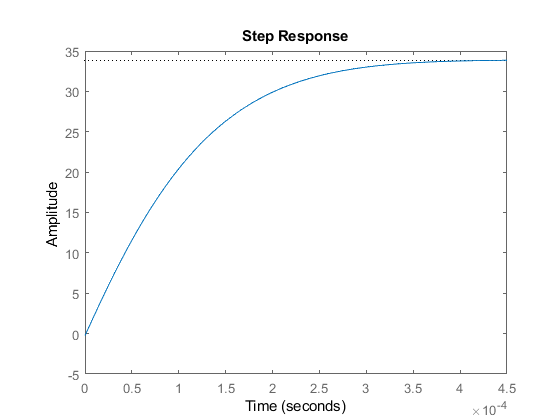

step(sys)

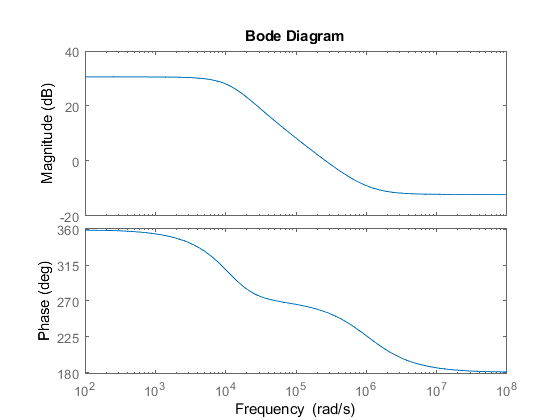

figure('Name', 'Bode');
bode(sys)

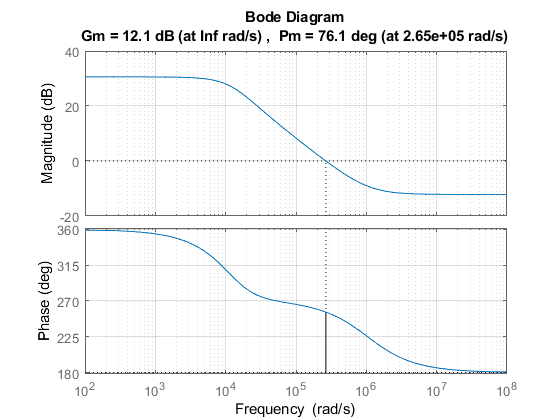

margin(sys)
grid on

 Here is an example of how the function nyquist works:
 Consider a randomly generated stable Transfer Function Model:
 of the form G(s)=num(s)/den(s):


num =     1.1275    0.5753   -1.0469    0.2498   -0.0072


den =     1.0000    7.2262   15.3642   10.1762    1.9687


Call nyquist using the following command (see also, help nyquist):
nyquist(tf(num,den));


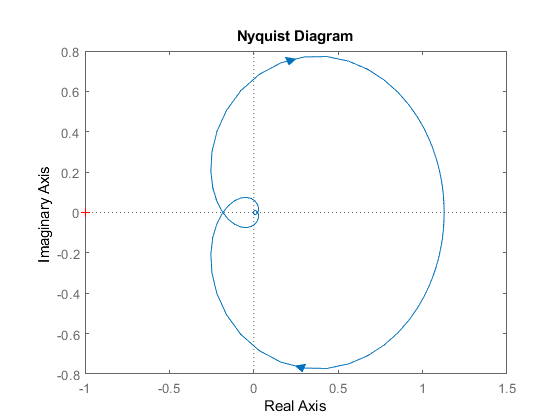


nyquist()


% bode con margenes de fase, polos ceros, margen de ganancia, root locus
% (QUE QUEDE BIEN CLARO CUALES SON LOS VALORES DEL CERO NO MINIMO)

Vo = vpa(subs(subs(Ys_Vs,s,0)*Vs/n,my_sims,my_vals))

$$Vo = 7.8644345292127073273855946533368$$